# Data analysis of localization confidence

- Compares confidence between unimodal and bimodal conditions

clear; clc; close all;
sub_slc     = 1;
ses_slc     = 1:2;

% manage path
cur_dir      = pwd;
[project_dir, ~]= fileparts(fileparts(cur_dir));
out_dir      = fullfile(cur_dir, 's1Fig');
addpath(genpath(fullfile(project_dir,'func')))
data_dir     = fullfile(project_dir, 'data','biLoc');
if ~exist(out_dir,'dir') mkdir(out_dir); end

% organize data
[bi_resp, bi_conf, bi_err, ExpInfo] = org_data_v2(sub_slc,ses_slc,'biLoc');
[uni_resp, uni_conf, uni_err, uniExpInfo] = org_data_v2(sub_slc,[],'uniLoc');

% summarize unimodal data
% condition (A,V1,V2) x loc (4) x rep
uni_pconf = mean(mean(uni_conf,3),2);
uni_idx = [1,1;2,3];

% organize by discrepancy
aud_locs = ExpInfo.speakerLocPixel(ExpInfo.audIdx);
conf_by_diff = org_by_diffs(bi_conf, aud_locs); % {diff} cue x reliability x rep 

% conditions
seq         = ExpInfo.randAVIdx;
audIdx      = ExpInfo.audIdx;
visIdx      = ExpInfo.visIdx;
cueIdx      = ExpInfo.cueIdx;
visReliIdx  = ExpInfo.visReliIdx;
num_rep     = ExpInfo.nRep;
cue_label   = {'Post-cue: A','Post-cue: V'};
rel_label   = {'High visual reliability','Low visual reliability'};
vis_locs    = round(ExpInfo.targetPixel);
diffs       = zeros(length(aud_locs), length(vis_locs));
for i = 1:length(aud_locs)
    for j = 1:length(vis_locs)
        diffs(i, j) = aud_locs(i) - aud_locs(j);
    end
end
diff_locs   = unique(abs(diffs))';

## Plot set up

lw = 2;
fontSZ = 15;
titleSZ = 20;
dotSZ = 80;
clt = [30, 120, 180; % blue
    227, 27, 27;  % dark red
    repmat(125, 1, 3)]./255; % gray
%     251, 154, 153]./255; % light red


## Is confidence modulated by cue discrepancy and cue reliability?

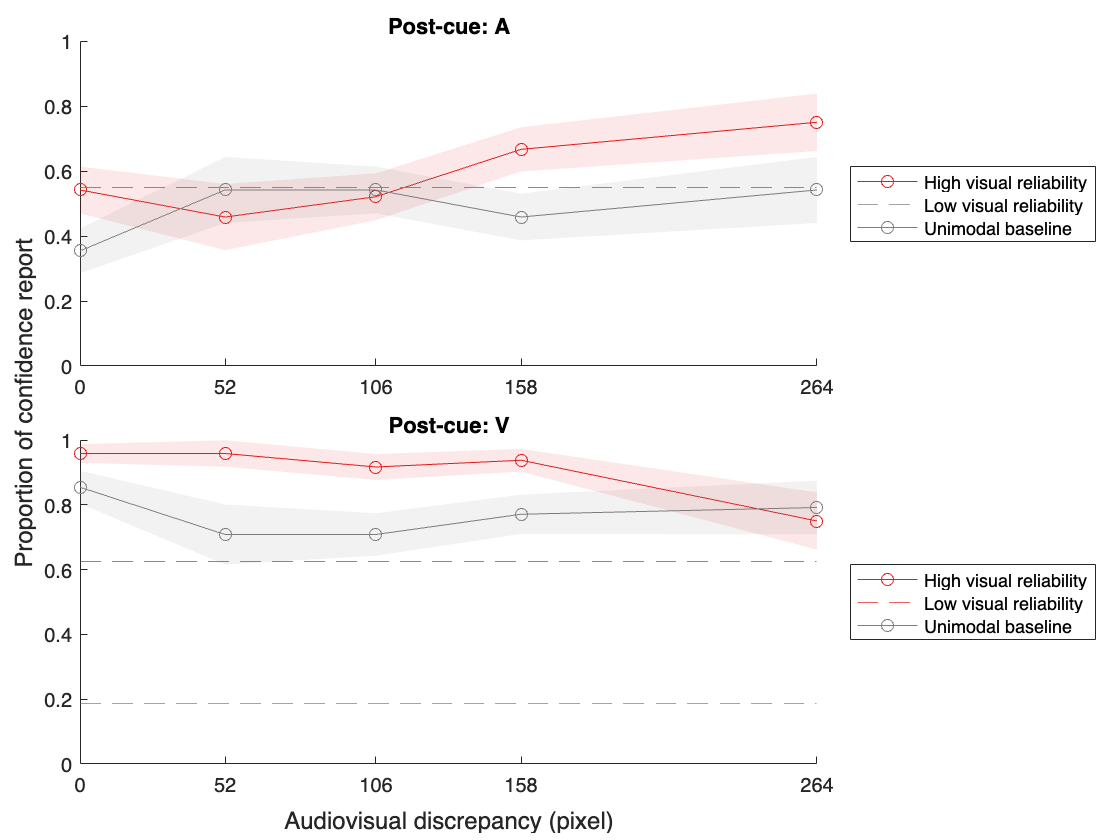

figure; hold on 

t = tiledlayout(2, 1);
xlabel(t, 'Audiovisual discrepancy (pixel)');
ylabel(t, 'Proportion of confidence report');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for cue = 1:numel(cueIdx)
    nexttile
    title(cue_label{cue})
    hold on
    for rel = 1:numel(visReliIdx)
        [p_conf, se_conf] = deal(NaN(1, numel(diff_locs)));
        for diff = 1:numel(diff_locs)
            i_conf = squeeze(conf_by_diff{diff}(cue, rel, :))';
            p = sum(i_conf)/numel(i_conf);
            p_conf(diff) = p;
            se_conf(diff) = sqrt((p*(1-p))/numel(i_conf));
        end
        plot(diff_locs, p_conf,'-o', 'Color',clt(rel+1,:))
        patch([diff_locs, fliplr(diff_locs)], ...
            [p_conf - se_conf, fliplr(p_conf + se_conf)], ...
            clt(rel+1,:),'EdgeColor','none','FaceAlpha',0.1, ...
            'HandleVisibility', 'off')
        
        if cue == 1
            yline(uni_pconf(1),'--','Color',repmat(0.5,1,3))
        else
            yline(uni_pconf(rel+1),'--','Color',clt(rel+1,:))
        end
        
        ylim([0, 1])
        xlim([min(diff_locs), max(diff_locs)])
    end
    xticks(diff_locs)
    legend([rel_label,{'Unimodal baseline'}], 'Location', 'eastoutside');
end